% Defining the variables
clc;
format compact
syms Pdyn y w theta alphaR a b g N a1 a2 a3 a4 a5 b1 b2 b3 b4 b5
% Given Data
[Clalphac,lambda,AR,M,g,N,mass,Vs,EI,GJ,m,c,s,ec,xcg,cmac0]= deal(5.422,0.61,9.43,0.8,9.81,3,66000,316.4,2E8 ,1.75E8 ,500,3.072,17.68,0.6875,-0.1123,-0.015);
% Clalphac= Cl alpha corrected (per radian)
% lambda =  Sweep angle wrt to EA axis (radian)
% AR =  Aspect Ratio
% M =  Mach Number
% g =  Acceleration Due To Gravity
% N = Load Factor
% mass =  Mass in Kg
% Vs = Velocity Of Sound (m/sec) at 6 Km
%Pdyn = (0.5*0.6601*((M*Vs)^2)); % Dynamic Pressure at 6 km
% % Properties Of Wing
% EI = Variation Of Product Of E and I with y
% GJ =  Variation Of Product Of G and J with y
% m = Variation Of Mass Of Wing With y
% c =  Variation Of Chord Length With y
% s = Span(m) in y' direction i.e. Elastic Axis
% ec = Distance from EA to AC
% xcg =  Distance from EA to AC
% cmac0 = Aerodynamic Moment Co-Efficent
% % Assuming Approximate Function For 'w' And 'theta'
ai =5; %Number Of constants In The Approximate Function For w
bi = ai; % Number Of constants In The Approximate Function For theta
a = sym('a',[1 ai]); % Creating an array for a's parameters
a = a.'; % Converting it into a Column Vector
b = sym('b',[1 bi]); % Creating an array for b's parameters
b = b.'; % Converting it into a Column Vector
w = 0; % Initializing The Approximate Function For Deflection 'w' 
theta =0; % Initialing The Approximate Function For Theta  
for i = 1:ai
 w = a(i,1)*y^(i+1) + w;
end
for i = 1:bi
 theta = b(i,1)*y^(i) + theta;
end
% Effective Total Angle Of Attack
phi = diff(w,y); 
alphaT = (alphaR + theta - phi*tan(lambda));
% Forces And Moment Relations
l = Pdyn*cos(lambda)^2*c*Clalphac*alphaT; % Running Lift / Unit Length 
Pz = l - (N*m*g); % Net Force Per Unit Length Of Span
my = (l*ec) - (N*m*g*xcg) + (Pdyn*(cos(lambda)^2)*(c^2)*cmac0);
% Twisting Moment Per Unit Length Of Span
% Differentitation Terms
dw_dy = diff(w, y); 
dw2_dy2 = diff((dw_dy), y);
dtheta_dy = diff(theta, y);
% Strain Energy, Worrk Done And Potential Energy Functional
UB = 0.5*int((EI*((dw2_dy2)^2)),y,[0 s]); % Bending Strain Energy
UT = 0.5*int((GJ*((dtheta_dy)^2)),y,[0 s]); 
% Torsional Strain Energy
WeB = int((Pz*w), y,[0 s]); % Workdone In Bending
WeT = int((my*theta), y,[0 s]); % Workdone In Twisting
PEB = vpa((UB-WeB), 4); % Bending Energy Functional 
PET = vpa((UT-WeT), 4); % Twisting Energy Functional
PEF = PEB+PET;
% Rayleigh Ritz Method Minimizing The Potential Energy Functional
eqn = cell(ai+bi, 1); % Cell Defined For Equation
Coeff = cell(ai+bi, 1); % Cell Defined For Co-efficients
for i = 1:ai
 eqn{i} = diff(PEB, a(i)); % Differentiation wrt to ai
end
for i = 1:bi
 eqn{i+ai} = diff(PET, b(i)); % Differentiation wrt to bi
end
for i = 1:ai+bi
 Coeff{i} = fliplr(coeffs(eqn{i}, [a b]));
end
% Eigen Value Analysis For PdynD
Coeff_exp = vpa(cell2sym(Coeff), 4); % Expanding The Cell
Coeff_sq = Coeff_exp(1:ai+bi, 1:ai+bi); % Converting in to square matrix
Dm = det(Coeff_sq); 
PdynD = solve(Dm==0, Pdyn); % Value Of PdynD
PdynD = vpa(subs(PdynD), 5);
PdynD = PdynD(imag(PdynD)==0); % Taking Only The Real Terms
PdynD = PdynD(PdynD>=0); % Taking Only Positive Terms
PdynD = vpa(min(PdynD), 4); % The Minimum Value Of Dynamic Pressure Is Divergence
% Divergence Velocity And Mach Number
VDiv = vpa((2*PdynD)/0.6601)^0.5; % rho of air at 6000 m
MDiv = VDiv/316; % Speed of sound 316 m/sec at 6000 m
Pdyn = PdynD; % Replacing Pdyn with PdynD for perturbation Solution
Coeff_sq = subs((Coeff_sq), Pdyn);
[Eve, Eval] = eig(Coeff_sq); % Eigen Value And Eigen Vector For Mode Shapes
% Displaying the input approximate functions and the desired output
% disp('Approximate Functions');
% fprintf('\n w = %s \n', w);
fprintf('\n theta = %s \n', theta);


 theta = b1*y + b2*y^2 + b3*y^3 + b4*y^4 + b5*y^5 


fprintf('Divergence Dynamic Pressure, PdynD = %f Pa\n', PdynD);

Divergence Dynamic Pressure, PdynD = 108917.393901 Pa


fprintf('Divergence Velocity V(Div) = %f m/s\n', VDiv);

Divergence Velocity V(Div) = 574.458622 m/s


fprintf('Divergence Mach Number M(Div) = %f m/s \n', MDiv);

Divergence Mach Number M(Div) = 1.817907 m/s 


% % Mode Shapes For Deflection
[a1,a2,a3,a4,a5]=deal(Eve(1,1),Eve(2,1),Eve(3,1),Eve(4,1),Eve(5,1))

$$a1 = 0.0000029411105445901321264278023879836$$

$$a2 = 0.000078340484737316692702176796534189$$

$$a3 = 0.0019394251860936876995483106094031$$

$$a4 = 0.045069602386192451049951438053374$$

$$a5 = 0.99897346860723616938676329825585$$

def_w = subs(w);
figure(1);
title('Displacement mode');
subplot(2,2,1);
fplot(def_w,[0 s]);
grid on;
hold on;
title('Mode w1');
xlabel('span(m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,2),Eve(2,2),Eve(3,2),Eve(4,2),Eve(5,2))

$$a1 = -0.000015741811738266538866542325864677$$

$$a2 = -0.00020573009260601731309387538055734$$

$$a3 = -0.0023734784199440232623808614557959$$

$$a4 = -0.020075895530205974176106388314555$$

$$a5 = 0.02408945204940784675196664304168$$

def_w = subs(w);
subplot(2,2,2);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w2');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,3),Eve(2,3),Eve(3,3),Eve(4,3),Eve(5,3))

$$a1 = 0.00045195719895170099833826872138534$$

$$a2 = 0.0074135791691255991484477450273951$$

$$a3 = 0.10120845659942009908324336022556$$

$$a4 = 0.99377654437202002806600589372156$$

$$a5 = -0.045066331931669680923542456233546$$

def_w = subs(w);
subplot(2,2,3);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w3');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,4),Eve(2,4),Eve(3,4),Eve(4,4),Eve(5,4))

$$a1 = -0.0038185287392426305631560566484035$$

$$a2 = -0.029653007566779158485289008892533$$

$$a3 = -0.14933591441712096972802726033489$$

$$a4 = 0.11125549285325732569484327234965$$

$$a5 = -0.0044617312478234226297744270032407$$

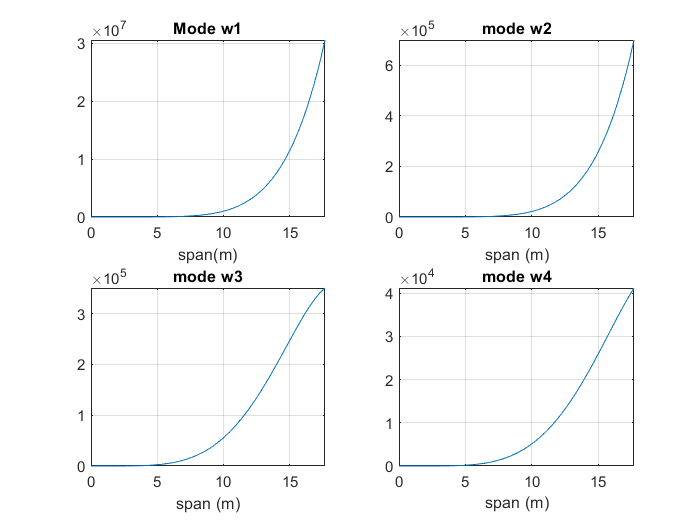

def_w = subs(w);
subplot(2,2,4);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w4');
xlabel('span (m)');

figure(2);
[a1,a2,a3,a4,a5]=deal(Eve(1,5),Eve(2,5),Eve(3,5),Eve(4,5),Eve(5,5))

$$a1 = 0.016457814752485819357659042331302$$

$$a2 = 0.16398544789813600404068502334304$$

$$a3 = 0.98111600554660303928609735545305$$

$$a4 = -0.10097221686277193138329153407524$$

$$a5 = 0.0026375964549652667385855706884448$$

def_w = subs(w);
subplot(2,2,1);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w5');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,6),Eve(2,6),Eve(3,6),Eve(4,6),Eve(5,6))

$$a1 = -0.14294233148946361131963054078888$$

$$a2 = -0.42764339514208436911433772273183$$

$$a3 = 0.27957353176333588529151407953062$$

$$a4 = -0.023081863730163437423587247277528$$

$$a5 = 0.00053800620695070318783080170415902$$

def_w = subs(w);
subplot(2,2,2);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w6');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,7),Eve(2,7),Eve(3,7),Eve(4,7),Eve(5,7))

$$a1 = 0.24376956517651483658204563361188$$

$$a2 = 0.95638623014567021158901255992434$$

$$a3 = -0.16059889579128982285517954914687$$

$$a4 = 0.0091300411289464553068722275716532$$

$$a5 = -0.00017577144913682156739883446499381$$

def_w = subs(w);
subplot(2,2,3);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w7');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,8),Eve(2,8),Eve(3,8),Eve(4,8),Eve(5,8))

$$a1 = 0.9143922746644025426583437270144$$

$$a2 = -0.34701756417450485356212270256701$$

$$a3 = 0.03836761324160927658969147372687$$

$$a4 = -0.0017763054249559393639027432131995$$

$$a5 = 0.000030059925505305639339923957249565$$

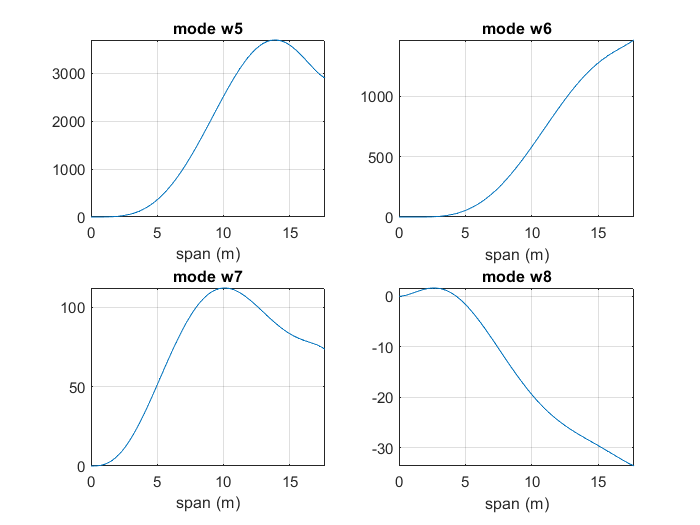

def_w = subs(w);
subplot(2,2,4);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w8');
xlabel('span (m)');

figure(3);
[a1,a2,a3,a4,a5]=deal(Eve(1,9),Eve(2,9),Eve(3,9),Eve(4,9),Eve(5,9))

$$a1 = 0.97530553094192768707123212717196$$

$$a2 = -0.21069796067034438805237567151514$$

$$a3 = 0.020145900691088027300748235756888$$

$$a4 = -0.00090802213489667301801578788225258$$

$$a5 = 0.000015544670914808971709013859993052$$


def_w = subs(w);
subplot(2,2,1);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w9');
xlabel('span (m)');
[a1,a2,a3,a4,a5]=deal(Eve(1,10),Eve(2,10),Eve(3,10),Eve(4,10),Eve(5,10))

$$a1 = 0.79699117994404785532425963011783$$

$$a2 = -0.044132883665680390826017908213836$$

$$a3 = -0.00009797512505011064721014985527564$$

$$a4 = 0.000038797027962895812480826727171403$$

$$a5 = -0.00000028356210948034608245265634744202$$

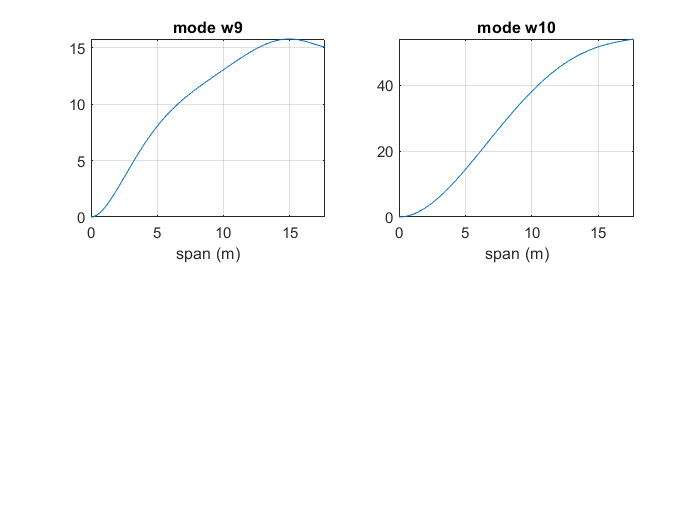

def_w = subs(w);
subplot(2,2,2);
fplot(def_w, [0 s]);
grid on;
hold on;
title('mode w10');
xlabel('span (m)');

%mode Shapes For Theta
figure(4);
title('Twisting Modes');
[b1,b2,b3,b4,b5]=deal(Eve(6,1),Eve(7,1),Eve(8,1),Eve(9,1),Eve(10,1))

$$b1 = 0.00000006513552691558679040819017697539$$

$$b2 = 0.0000010117729799831658326213971800084$$

$$b3 = 0.000015961664925702236868331438574346$$

$$b4 = 0.00025491686189919686999662659059712$$

$$b5 = 0.0041118372091508822404182123756594$$

def_theta = subs(theta);
subplot(2,2,1);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 1');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,2),Eve(7,2),Eve(8,2),Eve(9,2),Eve(10,2))

$$b1 = 0.0000024051923238900275290703222431496$$

$$b2 = 0.000093991610384068905240071476643436$$

$$b3 = 0.0023157251425020421309484273183157$$

$$b4 = 0.049656831525395509986413624759671$$

$$b5 = 0.99826840499228916207073915769576$$

def_theta = subs(theta);
subplot(2,2,2);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 2');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,3),Eve(7,3),Eve(8,3),Eve(9,3),Eve(10,3))

$$b1 = 0.000010531166296359492341034536340394$$

$$b2 = 0.00011430218210786002961822505750601$$

$$b3 = 0.0011341203119058359658080985888414$$

$$b4 = 0.0085861969983346299248952946875567$$

$$b5 = -0.0019662883606970530884082469030817$$

def_theta = subs(theta);
subplot(2,2,3);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 3');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,4),Eve(7,4),Eve(8,4),Eve(9,4),Eve(10,4))

$$b1 = 0.00012015302145879905059730251092301$$

$$b2 = 0.0065262841583480739298443291969224$$

$$b3 = 0.10106815807588881397884232149974$$

$$b4 = 0.9755808172667080094849057472362$$

$$b5 = -0.048907059742644485351037829920643$$

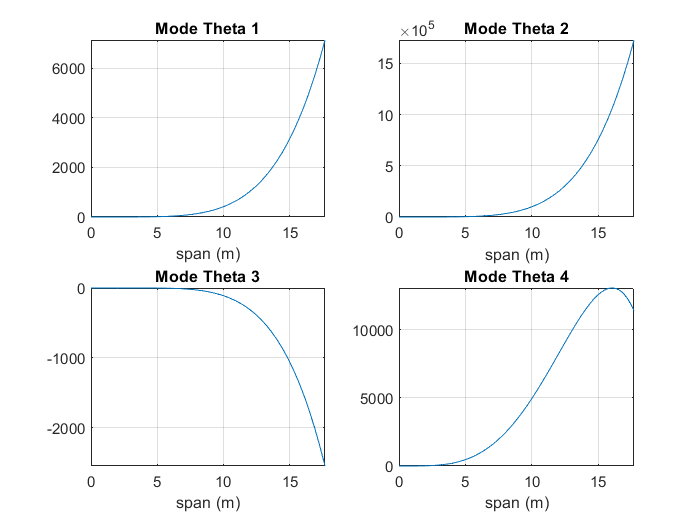

def_theta = subs(theta);
subplot(2,2,4);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 4');
xlabel('span (m)');

figure(5);
[b1,b2,b3,b4,b5]=deal(Eve(6,5),Eve(7,5),Eve(8,5),Eve(9,5),Eve(10,5))

$$b1 = 0.00026603169932372450094099874768167$$

$$b2 = 0.0015630225569816362337723988023779$$

$$b3 = 0.0064077681833443885183150786162394$$

$$b4 = -0.0018361800204300001732021167986642$$

$$b5 = 0.000080720004343635623126288434604811$$

def_theta = subs(theta);
subplot(2,2,1);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 5');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,6),Eve(7,6),Eve(8,6),Eve(9,6),Eve(10,6))

$$b1 = 0.0017421048901342831507624052496872$$

$$b2 = 0.12846048312460092854888085617232$$

$$b3 = 0.83300439668982692263515056819115$$

$$b4 = -0.087103652287685084724247891109614$$

$$b5 = 0.0023860244456560551596500771220053$$

def_theta = subs(theta);
subplot(2,2,2);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 6');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,7),Eve(7,7),Eve(8,7),Eve(9,7),Eve(10,7))

$$b1 = 0.0002872904409374888192097135512894$$

$$b2 = 0.0017308910929470199746510919490008$$

$$b3 = 0.0048111233329956712893606986230122$$

$$b4 = -0.00039812409257526005826255976426479$$

$$b5 = 0.0000086668553110154475833212083933255$$

def_theta = subs(theta);
subplot(2,2,3);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 7');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,8),Eve(7,8),Eve(8,8),Eve(9,8),Eve(10,8))

$$b1 = -0.01323863655766208402828171230781$$

$$b2 = -0.20210696686481275920518689190575$$

$$b3 = 0.031054439194315732515387803954485$$

$$b4 = -0.001865728188897817558880288691235$$

$$b5 = 0.00003986834551397455233410105315054$$

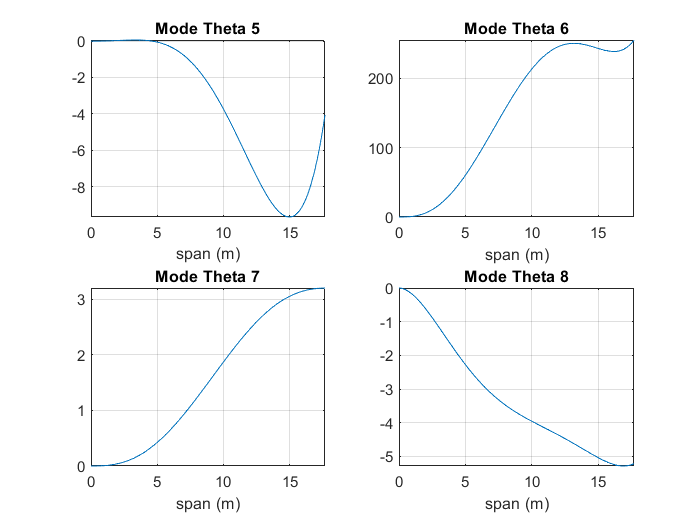

def_theta = subs(theta);
subplot(2,2,4);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 8');
xlabel('span (m)');

figure(6);
[b1,b2,b3,b4,b5]=deal(Eve(6,9),Eve(7,9),Eve(8,9),Eve(9,9),Eve(10,9))

$$b1 = -0.013924339122259856692095983541218$$

$$b2 = 0.060931786852963629536766932510201$$

$$b3 = -0.0084855439479863773542588677614758$$

$$b4 = 0.00048393814346171343195389156878289$$

$$b5 = -0.000010081989585073446389939082037904$$

def_theta = subs(theta);
subplot(2,2,1);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 9');
xlabel('span (m)');
[b1,b2,b3,b4,b5]=deal(Eve(6,10),Eve(7,10),Eve(8,10),Eve(9,10),Eve(10,10))

$$b1 = 0.60237608934095923913077129173658$$

$$b2 = -0.00060815626884181978119463817994224$$

$$b3 = 0.00010134087245637641344219755999891$$

$$b4 = -0.000058574749491256067513431508831749$$

$$b5 = 0.0000012659347929980011385630613826711$$

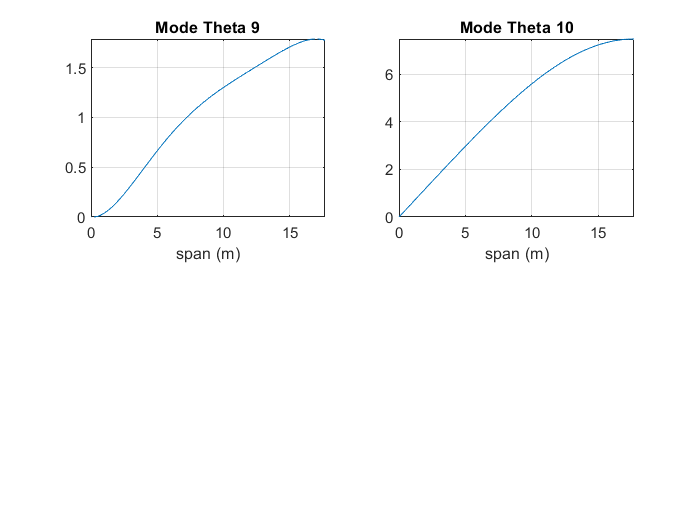

def_theta = subs(theta);
subplot(2,2,2);
fplot(def_theta, [0 s]);
grid on;
hold on;
title('Mode Theta 10');
xlabel('span (m)');

% % End Of Program
